# A Survey of US COVID Deaths Forecasting

Many models have been proposed for forecasting deaths due to COVID in the states of the US. Here we present a comparison of the forecasts generated by the following models, including our own. The following models have been considered:

- Covid19Sim_Simulator:  [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/Covid19Sim-Simulator](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/Covid19Sim-Simulator)

- YYG-ParamSearch: [https://github.com/youyanggu/covid19_projections](https://github.com/youyanggu/covid19_projections)

- IowaStateLW_STEM: [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/IowaStateLW-STEM](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/IowaStateLW-STEM)

- CovidActNow: [https://github.com/covid-projections/covid-data-model](https://github.com/covid-projections/covid-data-model)

- UCLA_SuEIR: [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/UCLA-SuEIR](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/UCLA-SuEIR)

- JHU_IDD: [https://github.com/HopkinsIDD/COVIDScenarioPipeline](https://github.com/HopkinsIDD/COVIDScenarioPipeline)

- CU _SELECT: [https://github.com/shaman-lab/COVID-19Projection](https://github.com/shaman-lab/COVID-19Projection)

- **[Our Model] SIkJ**$\alpha$ : [https://github.com/scc-usc/ReCOVER-COVID-19](https://github.com/scc-usc/ReCOVER-COVID-19)

These methods have used three different data sources:

- JHU ([https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)) is used by Covid19Sim_Simulator, YYG-ParamSearch, and IowaStateLW_STEM

- NYT ([https://github.com/nytimes/covid-19-data](https://github.com/nytimes/covid-19-data)) is used by CovidActNow and UCLA_SuEIR

- USF ([https://usafacts.org/visualizations/coronavirus-covid-19-spread-map/](https://usafacts.org/visualizations/coronavirus-covid-19-spread-map/)) is used by JHU_IDD and CU_SELECT

Since there are some discrepancies among different data sources, we perform a separate evaluation for each dataset. We train our model using each of the three datasets and use the forcasts in the respective evaluations. The chosen evaluation metric is Root Mean Squared Error (RMSE) of daily new deaths computed over the next two weeks from the day of the forecasts. More precisely, we skip the first day of the forecast to account for errors due to changing timezone or delayed reporting.

Finally, we also provide a combined comparison of all evaluations combined over all the datasets.

## Load US data from all sources (JHU, NYT, USF)

warning off;
addpath('./hyper_params/');
load_data_us;

## Identify days to evaluate on and classify methods based on datasets


lastday = 144;
firstday = 109;
skipdays = 7;

time_stamps =(firstday:lastday);

data_src = {'JHU', 'NYT', 'USF'}; % Next we list methods that use these data sources in order
method_list{1} = {'Covid19Sim_Simulator'; 'YYG_ParamSearch'};
method_list{2} = {'CovidActNow_SEIR_CAN'; 'UCLA_SuEIR'; 'IowaStateLW_STEM'};
method_list{3} = {'JHU_IDD_CovidSP'; 'CU_select'};


## Load others forecasts from files

for ml_idx = 1:length(method_list)
    methods = method_list{ml_idx};
    for mm = 1:length(methods)
        for tt = 1:length(time_stamps)
            try
                fname = [methods{mm}, '_', num2str(time_stamps(tt)), '.csv'];
                preds = readtable(['../results/others_death_forecasts/', fname]);
                preds = preds{2:end, 4:end};
                eval([methods{mm}, '{',  num2str(tt),'} = ', 'preds;']);
            catch
                eval([methods{mm}, '{',  num2str(tt),'} = ', '-1;']);
            end
        end
    end
end


## Append our method to method list

method_list{1} = [method_list{1}; {'SIkJa_JHU'}];
method_list{2} = [method_list{2}; {'SIkJa_NYT'}];
method_list{3} = [method_list{3}; {'SIkJa_USF'}];

## Set hyperparameters for death forecasts

These may be further tuned or chosen based on a validation set. Currently, we have set them to what we assumed to be reasonable values.

dk = 3;
djp = 7;
dalpha = 1;
dwin = 49;
horizon = 20;
dhorizon = horizon; % days of deaths predcitions
un = 40;
T_val = 14; % For error calculation

## Generate own results with all data sources

for ds = 1:length(data_src)
    
    eval(['data_4 = data_4_', data_src{ds}, ';']);
    eval(['deaths = deaths_', data_src{ds}, ';']);
    data_4_s = [data_4(:, 1) cumsum(movmean(diff(data_4')', 7, 2), 2)];
    deaths_s = [deaths(:, 1) cumsum(movmean(diff(deaths')', 7, 2), 2)];
    
    for tt = 1:length(time_stamps) % Initialize with a default '-1' value
        eval(['SIkJa_', data_src{ds}, '{tt} = -1;']);
    end
    for tt = 1:skipdays:length(time_stamps) % Pick some days and generate forecasts
        T_full = time_stamps(tt);
        eval(['load us_hyperparam_ref_' num2str(time_stamps(tt) - 3)]);
        best_param_list = best_param_list_no;
        
        beta_after = var_ind_beta_un(data_4_s(:, 1:T_full), passengerFlow*0, best_param_list(:, 3)*0.1, best_param_list(:, 1), un, popu, best_param_list(:, 2));
        infec_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_after, popu, best_param_list(:, 1), horizon, best_param_list(:, 2), un);
        
%         [beta_all_cell, un_prob, init_dat] = learn_nonlin(data_4_s(:, 1:T_full), popu, best_param_list(:, 1), best_param_list(:, 2), best_param_list(:, 3)*0.1, [], 'll');
%         infec_un = var_simulate_pred_un(init_dat, passengerFlow*0, beta_all_cell, popu, best_param_list(:, 1), horizon, best_param_list(:, 2), un_prob);
        
        infec_data = [data_4_s(:, T_full-dk*djp:T_full), infec_un];
        
        base_deaths = deaths(:, T_full);
        
        [death_rates] = var_ind_deaths(data_4_s, deaths_s, dalpha, dk, djp, dwin);
        [pred_deaths] = var_simulate_deaths(infec_data, death_rates, dk, djp, dhorizon, base_deaths);
        
        preds = diff(pred_deaths')';
        eval(['SIkJa_', data_src{ds}, '{tt} = preds(:, 1:T_val);']);
        fprintf('.');
    end
    disp(['Done for data source ', data_src{ds}, '!']);
end

......

Done for data source JHU!


......

Done for data source NYT!


......

Done for data source USF!


## Evaluate all models

We evaluate RMSE as well as symmetric MAPE, however, MAPE is likely to skew the evaluation due to higher error on close-to-zero values. One may choose to ignore computing errors on values that are too small. By default, nothing is ignored. One can select a different value of "filterval" below.

filterval = 0; % Ignore evaluation on data where ground truth is consistently less than or equal to this number. Choose -1 to avoid ignoring
for ds = 1:length(data_src)
    methods = method_list{ds};
    for mm = 1:length(methods)
        eval(['MSE_' methods{mm}, ' = -1*ones(length(time_stamps), 1);']);
        eval(['listMSE_' methods{mm},' = -1*ones(length(countries), length(time_stamps));']);
        for tt = 1:length(time_stamps)
            eval(['preds = ' methods{mm}, '{',  num2str(tt),'};']);
            eval(['deaths = deaths_', data_src{ds}, ';']);
            gt = deaths(:, time_stamps(tt):end);
            gt = diff(gt')';
            gt = gt(:, 1:T_val);
            eval(['preds = ', methods{mm}, '{',  num2str(tt),'};']);
            if length(preds)==1
                continue;
            end
            preds = (preds + abs(preds))/2; % Replace negative values by 0
            
            cidx = all(gt > filterval, 2); % Ignore consistenty low values. Only pick high values
            cidx([51, 52, 53, 55, 56]) = 0; % We do not evaluate on these regions as not all models have provided results for these
            
            [meanMSE, meanMAPE, listMSE] = calc_errors(gt(cidx, 1:end), preds(cidx, 1:end), 7);
            eval(['MSE_' methods{mm}, '(',  num2str(tt),') = meanMSE;']);
            eval(['MAPE_' methods{mm}, '(',  num2str(tt),') = meanMAPE;']);
            eval(['listMSE_' methods{mm}, '(cidx, ',  num2str(tt),') = listMSE;']);
        end
    end
end

## Present results

Here we present the rankings.

for ds = 1:length(data_src)
    methods = method_list{ds};
    fprintf('__________________');
    disp(['Leaderboard on ' data_src{ds} ' dataset']);
    fprintf('__________________');
    res_avg = zeros(length(methods), 1);
    res_lat = zeros(length(methods), 1);
    for mm = 1:length(methods)
        eval(['preds = ', methods{mm}, '{',  num2str(tt),'};']);
        eval(['meanMSE = MSE_' methods{mm} ';']);
        meanMSE(meanMSE<0) = NaN;
        res_avg(mm) = nanmean(meanMSE);
        res_lat(mm) = meanMSE(end);
    end
    disp('Running Average Performance');
    fprintf('_________\n');
    [~, idx] = sort(res_avg);
    for mm = 1:length(methods)
        disp([num2str(mm) '. ' methods{idx(mm)} ' (RMSE =' num2str(res_avg(idx(mm))) ')']);
    end
    fprintf('_________\n');
    disp(['Recent Performance (' datestr(datenum(2020, 1, 22)+lastday) ')']);
    fprintf('_________\n');
    [~, idx] = sort(res_lat);
    for mm = 1:length(methods)
        disp([num2str(mm) '. ' methods{idx(mm)} ' (RMSE =' num2str(res_lat(idx(mm))) ')']);
    end
    fprintf('____________________________\n');
    
end

__________________

Leaderboard on JHU dataset


__________________

Running Average Performance


_________


1. SIkJa_JHU (RMSE =170.1271)
2. Covid19Sim_Simulator (RMSE =190.9792)
3. YYG_ParamSearch (RMSE =372.8043)


_________


Recent Performance (14-Jun-2020)


_________


1. SIkJa_JHU (RMSE =97.9454)
2. YYG_ParamSearch (RMSE =286.4577)
3. Covid19Sim_Simulator (RMSE =302.8036)


____________________________


__________________

Leaderboard on NYT dataset


__________________

Running Average Performance


_________


1. SIkJa_NYT (RMSE =150.8646)
2. UCLA_SuEIR (RMSE =195.8618)
3. CovidActNow_SEIR_CAN (RMSE =323.0022)
4. IowaStateLW_STEM (RMSE =851.1376)


_________


Recent Performance (14-Jun-2020)


_________


1. SIkJa_NYT (RMSE =82.3437)
2. UCLA_SuEIR (RMSE =193.2007)
3. CovidActNow_SEIR_CAN (RMSE =403.2673)
4. IowaStateLW_STEM (RMSE =726.7303)


____________________________


__________________

Leaderboard on USF dataset


__________________

Running Average Performance


_________


1. SIkJa_USF (RMSE =161.6603)
2. CU_select (RMSE =427.1502)
3. JHU_IDD_CovidSP (RMSE =1185.3537)


_________


Recent Performance (14-Jun-2020)


_________


1. SIkJa_USF (RMSE =110.3518)
2. JHU_IDD_CovidSP (RMSE =197.4095)
3. CU_select (RMSE =540.491)


____________________________


## Plot results

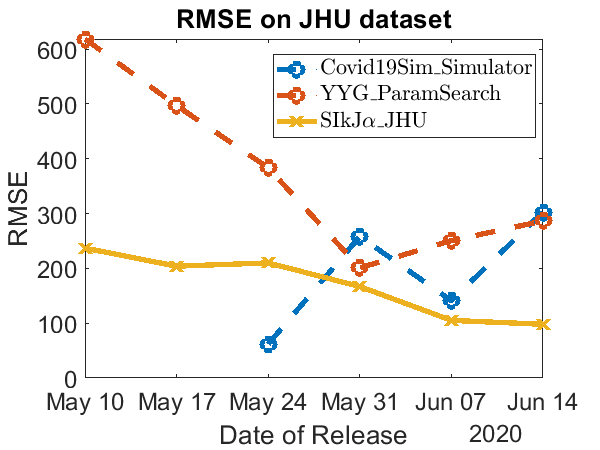

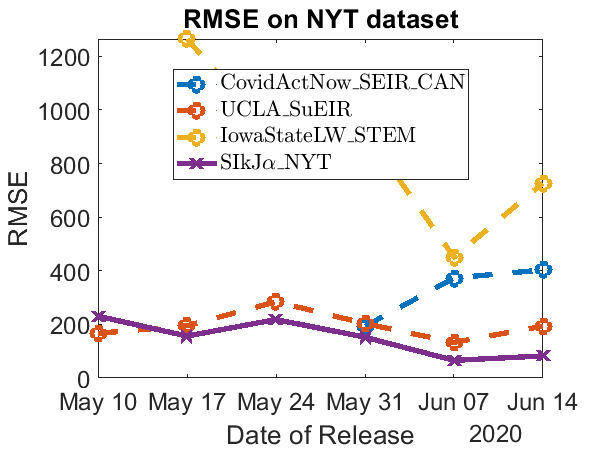

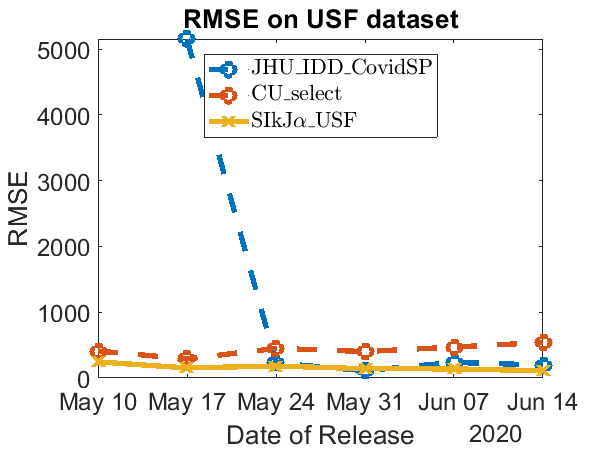

for ds = 1:length(data_src)
    methods = method_list{ds};
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,600,450]);
    for mm = 1:length(methods)
        for tt = 1:length(time_stamps)
            eval(['meanMSE(tt) = MSE_' methods{mm} '(' num2str(tt) ');']);
            eval(['meanMAPE(tt) = MAPE_' methods{mm} '(' num2str(tt) ');']);
        end
        meanMSE(meanMSE < 0) = NaN;
        meanMAPE(meanMAPE < 0) = NaN;
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        if startsWith(methods{mm}, 'SIkJ')
            plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 10); hold on;
        else
            plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'o', 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10); hold on;
        end
    end
    title(['RMSE on ' data_src{ds} ' dataset']);
    xlabel('Date of Release');
    ylabel('RMSE')
    ylim([0, Inf]);
    ll = strrep(methods(1:end-1), '_', '\_');
    ll = [ll; {['SIkJ$\alpha$\_', data_src{ds}]}];
    legend(ll, "Interpreter","latex", 'location', 'best');
    hold off;
end

## Plot all in one

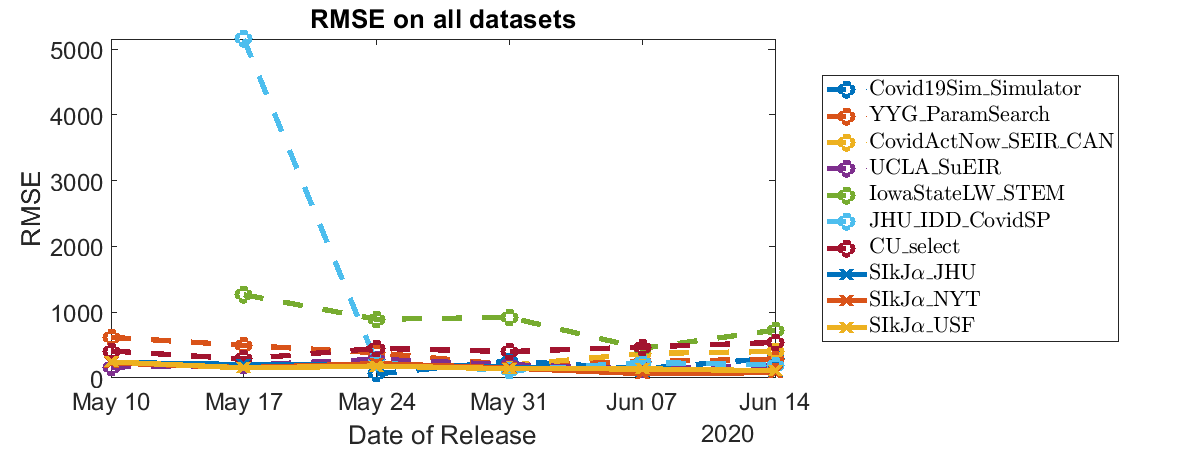

ll = [];
figure('DefaultAxesFontSize',18);
%axes('Position',[0.15 0.15 0.7 0.7])
set(gcf,'position',[10,10,1200,450]);

for ds = 1:length(data_src)
    methods = method_list{ds};
    for mm = 1:length(methods)-1
        for tt = 1:length(time_stamps)
            eval(['meanMSE(tt) = MSE_' methods{mm} '(' num2str(tt) ');']);
            eval(['meanMAPE(tt) = MAPE_' methods{mm} '(' num2str(tt) ');']);
        end
        meanMSE(meanMSE < 0) = NaN;
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'o', 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10); hold on;
    end
        ll = [ll; methods(1:end-1)];
end

for ds = 1:length(data_src)
        for tt = 1:length(time_stamps)
            eval(['meanMSE(tt) = MSE_SIkJa_' data_src{ds} '(' num2str(tt) ');']);
            eval(['meanMAPE(tt) = MAPE_SIkJa_' data_src{ds} '(' num2str(tt) ');']);
        end
        meanMSE(meanMSE < 0) = NaN;
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 10); hold on;
        ll = [ll; {['SIkJa_' data_src{ds}]}];
end

title(['RMSE on all datasets']);
xlabel('Date of Release');
ylabel('RMSE');
ylim([0, Inf]);
ll = strrep(ll, '_', '\_');
ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
legend(ll, "Interpreter","latex", 'location', 'eastoutside');

hold off;

## Evaluation on States with High Deaths

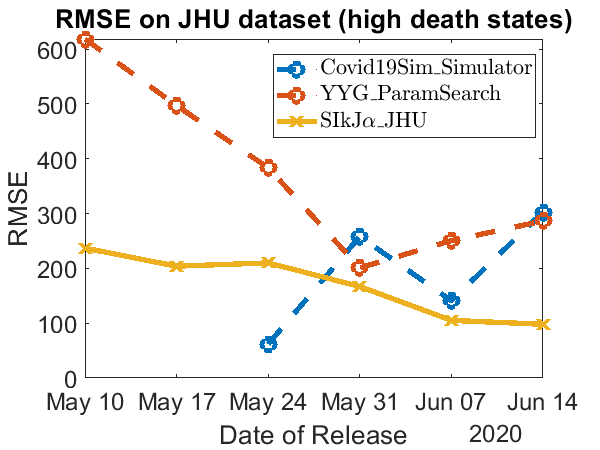

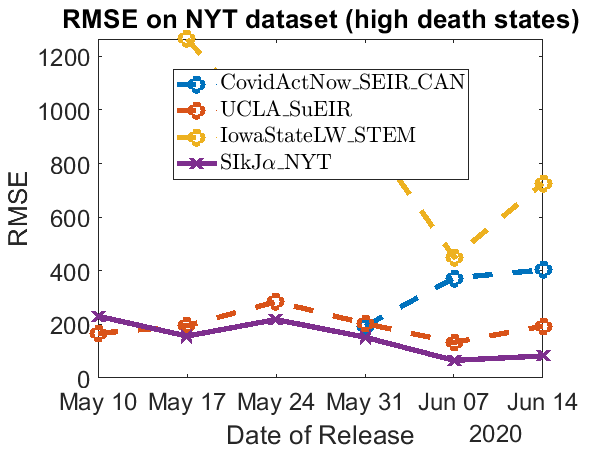

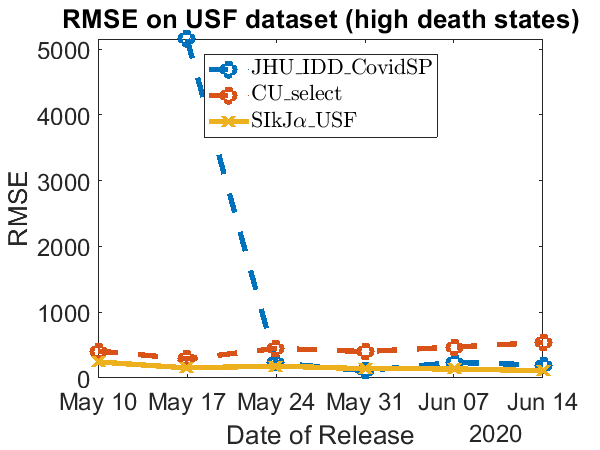

[~, sidx] = sort(deaths(:, firstday), 'descend');
cidx = deaths(:, firstday) >= deaths(sidx(25), firstday); % These are the indices of states with top 25 deaths on the first day of forecasting
for ds = 1:length(data_src)
    methods = method_list{ds};
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,600,450]);
    for mm = 1:length(methods)
        eval(['listMSE = listMSE_' methods{mm} ';']);
        listMSE(listMSE==-1) = NaN;
        
        meanMSE = sqrt(nanmean(listMSE(cidx, :), 1));
        meanMSE(meanMSE < 0) = NaN;
       
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        if startsWith(methods{mm}, 'SIkJ')
            plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 10); hold on;
        else
            plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'o', 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10); hold on;
        end
    end
    title(['RMSE on ' data_src{ds} ' dataset (high death states)']);
    xlabel('Date of Release');
    ylabel('RMSE')
    ylim([0, Inf]);
    ll = strrep(methods(1:end-1), '_', '\_');
    ll = [ll; {['SIkJ$\alpha$\_', data_src{ds}]}];
    legend(ll, "Interpreter","latex", 'location', 'best');
    hold off;
end

## Evaluation on States with Low Deaths

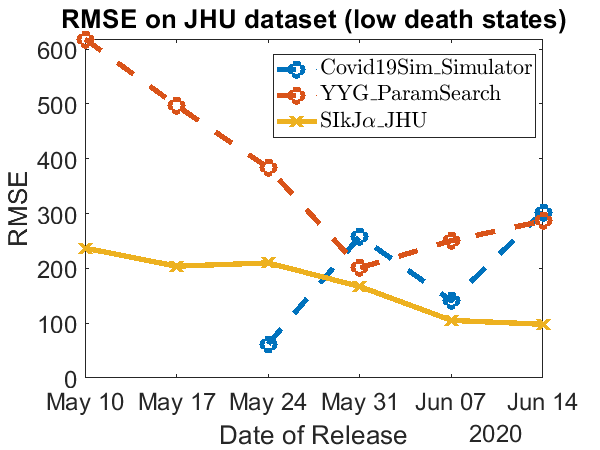

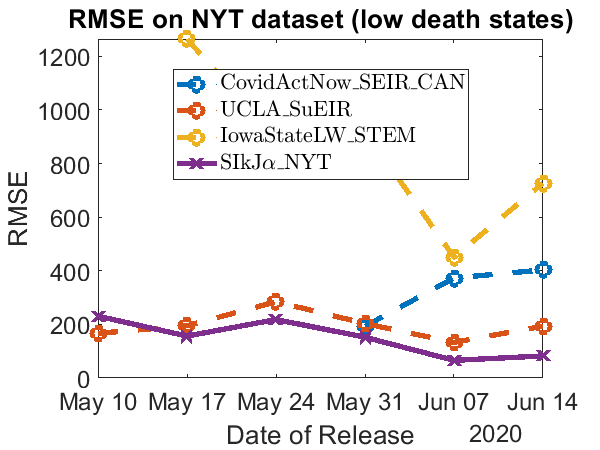

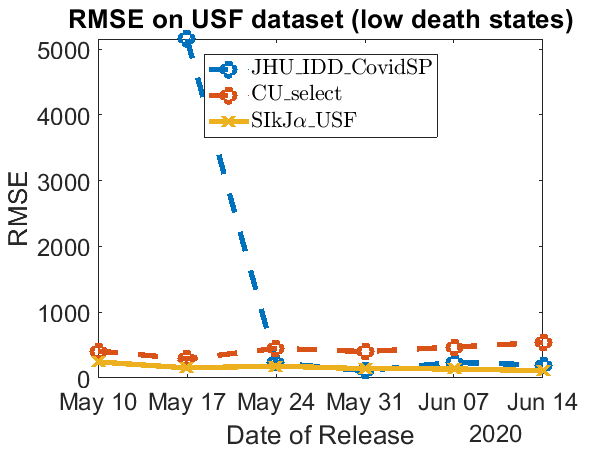

[~, sidx] = sort(deaths(:, firstday), 'descend');
cidx = deaths(:, firstday) <= deaths(sidx(25), firstday); % These are the indices of states with top 25 deaths on the first day of forecasting
for ds = 1:length(data_src)
    methods = method_list{ds};
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,600,450]);
    for mm = 1:length(methods)
        eval(['listMSE = listMSE_' methods{mm} ';']);
        listMSE(listMSE==-1) = NaN;
        
        meanMSE = sqrt(nanmean(listMSE(cidx, :), 1));
        meanMSE(meanMSE < 0) = NaN;
       
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        if startsWith(methods{mm}, 'SIkJ')
            plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 10); hold on;
        else
            plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'o', 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10); hold on;
        end
    end
    title(['RMSE on ' data_src{ds} ' dataset (low death states)']);
    xlabel('Date of Release');
    ylabel('RMSE')
    ylim([0, Inf]);
    ll = strrep(methods(1:end-1), '_', '\_');
    ll = [ll; {['SIkJ$\alpha$\_', data_src{ds}]}];
    legend(ll, "Interpreter","latex", 'location', 'best');
    hold off;
end

## Data Source Differences

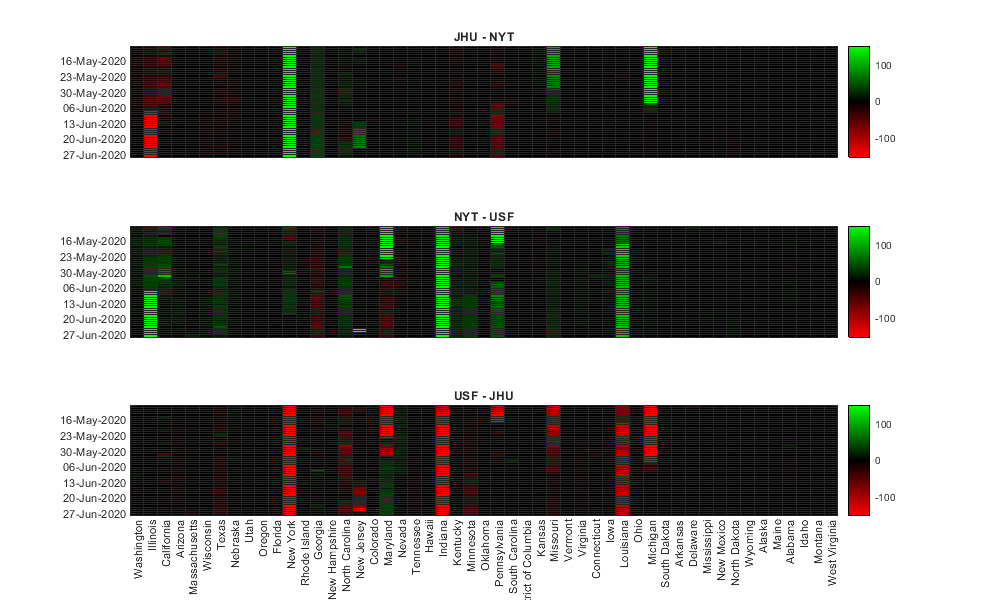

cidx = ones(length(countries), 1)==1; cidx([51, 52, 53, 55, 56]) = 0;
all_data = zeros(sum(cidx), lastday-firstday+15, length(data_src));
for ds = 1:length(data_src)
    eval(['all_data(:, :, ds) = deaths_' data_src{ds} '(cidx, firstday:lastday+14);']);
end
Tx = datetime(2020, 1, 22)+ caldays([time_stamps (time_stamps(end)+1:time_stamps(end)+14)]);
these_regions = countries(cidx);
datelabels = cellstr(datestr(Tx));
for ii = 1:length(datelabels)
    if mod(ii, 7) ~= 0
        datelabels{ii} = '';
    end
end

climit = 150;
mymap = [(climit:-1:0)' zeros(climit+1, 1) zeros(climit+1, 1); zeros(climit, 1) (1:climit)'  zeros(climit, 1)]./climit;

figure('DefaultAxesFontSize',12);
set(gcf,'position',[10,10,1000, 600]);

death_range = all_data(:, :, 1) - all_data(:, :, 2);
subplot(3, 1, 1); h = heatmap(these_regions, Tx', death_range', 'YDisplayLabels', datelabels, 'XDisplayLabels', nan(length(these_regions), 1), 'ColorLimits',[-climit, climit], 'Colormap', mymap, 'Title', 'JHU - NYT');

death_range = all_data(:, :, 2) - all_data(:, :, 3);
subplot(3, 1, 2); heatmap(these_regions, Tx', death_range', 'YDisplayLabels', datelabels, 'XDisplayLabels', nan(length(these_regions), 1),'ColorLimits',[-climit, climit], 'Colormap', mymap, 'Title', 'NYT - USF');

death_range = all_data(:, :, 3) - all_data(:, :, 1);
subplot(3, 1, 3); heatmap(these_regions, Tx, death_range', 'YDisplayLabels', datelabels,  'ColorLimits',[-climit, climit], 'Colormap', mymap, 'Title', 'USF - JHU');

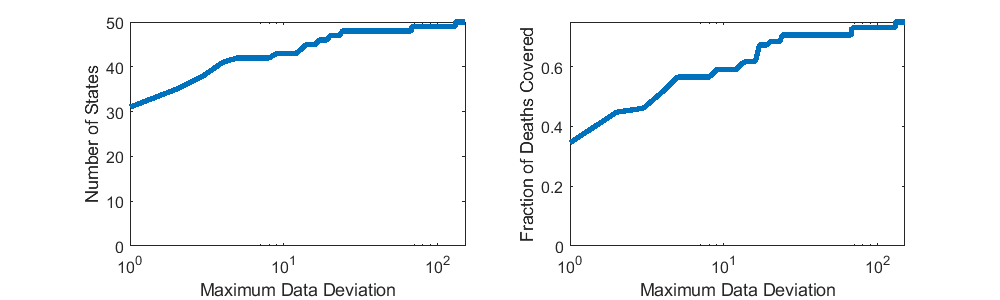

cut_offs = zeros(climit, 1);
death_coverage = zeros(climit, 1);
figure('DefaultAxesFontSize',12);
set(gcf,'position',[10,10,1000, 300]);
death_range = range(all_data, 3);

for ii = 1:climit
    cidx = any(death_range < ii, 2);
    cut_offs(ii) = sum(cidx);
    death_coverage(ii) = sum(deaths_USF(cidx, end))./sum(deaths_USF(:, end));
end

subplot(1, 2, 1); semilogx(cut_offs, 'LineWidth', 4);
ylabel('Number of States');
xlabel('Maximum Data Deviation');
ylim([0, Inf]);

subplot(1, 2, 2); semilogx(death_coverage, 'LineWidth', 4);
ylabel('Fraction of Deaths Covered');
xlabel('Maximum Data Deviation');
ylim([0, Inf]);

## Comparison of all methods on no-conflict states

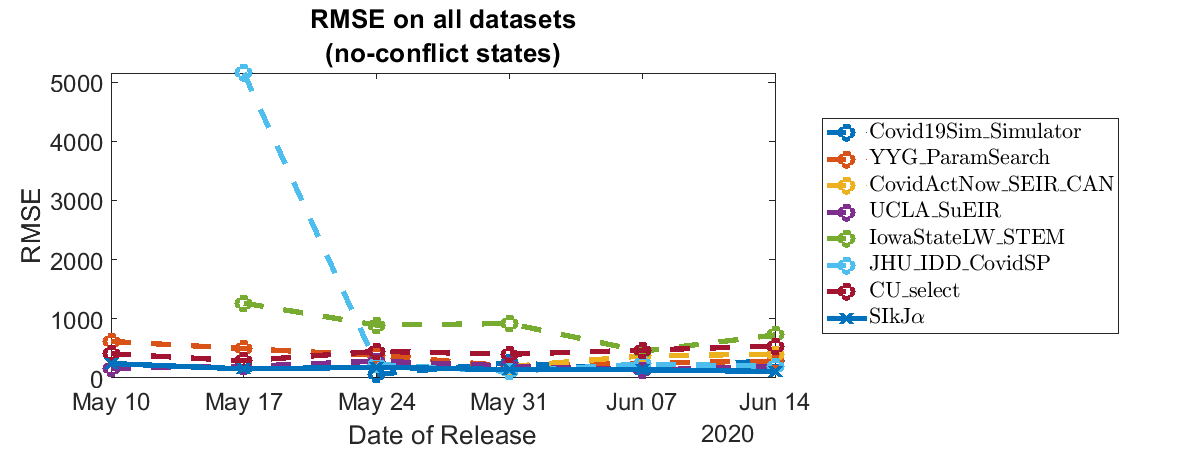

cidx = any(death_range < 1, 2);
ll = [];
figure('DefaultAxesFontSize',18);
%axes('Position',[0.15 0.15 0.7 0.7])
set(gcf,'position',[10,10,1200,450]);

for ds = 1:length(data_src)
    methods = method_list{ds};
    for mm = 1:length(methods)-1
        eval(['listMSE = listMSE_' methods{mm} ';']);
        listMSE(listMSE==-1) = NaN;
        meanMSE = sqrt(nanmean(listMSE(cidx, :), 1));
        meanMSE(meanMSE < 0) = NaN;
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'o', 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10); hold on;
    end
        ll = [ll; methods(1:end-1)];
end

for ds = 1:1
        eval(['listMSE = listMSE_' methods{length(methods)} ';']);
        listMSE(listMSE==-1) = NaN;
        meanMSE = sqrt(nanmean(listMSE(cidx, :), 1));
        meanMSE(meanMSE < 0) = NaN;
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 10); hold on;
        ll = [ll; {['SIkJa' ]}];
end

title({'RMSE on all datasets'; '(no-conflict states)'});
xlabel('Date of Release');
ylabel('RMSE');
ylim([0, Inf]);
ll = strrep(ll, '_', '\_');
ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
legend(ll, "Interpreter","latex", 'location', 'eastoutside');

hold off;